% Consider an unity feedback system with open loop transfer function 
% 20 / s(s^2 + 12s + 22)
% 
% Using a Matlab script, find the poles of closed loop transfer function. Plot the
% unit step response of the closed loop system. From the plot calculate td,
% tr, tp, Mp, ts. Using dominant pole concept can this system can be
% approximated to a lower order system? If so, write the approximate closed
% loop transfer function and justify your answer through simulation
% results.

clc
clear
close

numerator = 20;
denominator = [1, 12, 22, 20];
system = tf(numerator, denominator);

poles = pole(system)

poles =  -10.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


stepinfo(system)

ans = struct with fields:
         RiseTime: 1.5364
    TransientTime: 4.3181
     SettlingTime: 4.3181
      SettlingMin: 0.9122
      SettlingMax: 1.0427
        Overshoot: 4.2710
       Undershoot: 0
             Peak: 1.0427
         PeakTime: 3.2697


magnitudes = abs(poles);
dominant_pole_distance = min(magnitudes);
dominant_poles = [];
for pole=1:length(poles)
    if abs(poles(pole)) == dominant_pole_distance
        dominant_poles(end + 1) = poles(pole);
    end
end
dominant_poles

dominant_poles =   -1.0000 + 1.0000i  -1.0000 - 1.0000i


system2 = zpk([], dominant_poles, 1);

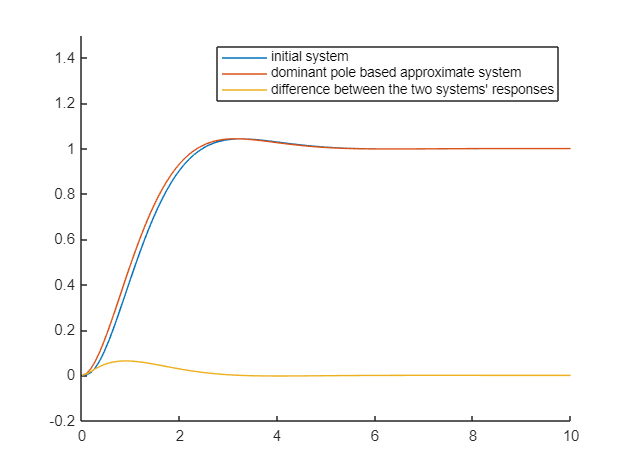

x = step(system, [0 10]);
time = linspace(0, 10, length(x));
steadystate1 = mean(x(end - 5 : end));
hold on
plot(time, x);
y = step(system2, [0 10]);
time = linspace(0, 10, length(y));
steadystate2 = mean(y(end - 5 : end));
gain = steadystate1/steadystate2;
steadystate1 = mean(x(end - 5 : end));
system2 = zpk([], dominant_poles, gain);
y = step(system2, [0 10]);
plot(time, y);
plot(time, y-x)

ylim([-0.2 1.5])
legend("initial system", "dominant pole based approximate system", "difference between the two systems' responses");